name = getenv('COMPUTERNAME'); 
if name == 'DESKTOP-9DDE2RH'
    load('\\storage1.ris.wustl.edu\crponce\Active\Data-Ephys-MAT\monkey64chan-10062019-001_formatted')
else
    load('D:\Monkey_Data\monkey64chan-10062019-001_formatted.mat')
end
delete name

### Transpose Data Back and Forth

rasters = permute(rasters,[3,2,1]);
lfps = permute(lfps,[3,2,1]);

trial_i=10;
figure(1);
subplot(1,2,1)
title("RASTER")
imagesc(permute(rasters(28,:,trial_i:trial_i+50),[1,3,2]));colorbar()
subplot(1,2,2)
title("LFP")
imagesc(permute(lfps(28,:,trial_i:trial_i+50),[1,3,2]));colorbar()

channel_j = 28
figure(3);
subplot(1,2,1)
title("RASTER")
imagesc(rasters(sort_idx, :, channel_j));colorbar()
subplot(1,2,2)
title("LFP")
imagesc(lfps(sort_idx, :, channel_j));colorbar()

## Sort out image names and generation number

[Sort_Name, sort_idx] = sort(Trials.imageName);% Trials.imageName

gen_num_i = zeros([length(Sort_Name),1]);
block_i = 0;
natural_stim_i = zeros([length(Sort_Name),1]);
stim_i = 1;
for i = 1:length(Sort_Name)
    if ~contains(Sort_Name{i}, "block")
        while ~contains(Sort_Name{i}, sprintf("[%02d]", stim_i))
            stim_i = stim_i + 1;
        end
        natural_stim_i(i) = stim_i;
        gen_num_i(i) = -1;
    else
        while ~contains(Sort_Name{i}, sprintf("block%03d", block_i))
            block_i = block_i + 1;
        end
        gen_num_i(i) = block_i;
    end
end

### PSTH of natural stimuli 

nat_stim_fr = zeros(max(natural_stim_i), size(rasters, 2), size(rasters, 3));
nat_stim_fr_std = zeros(max(natural_stim_i), size(rasters, 2), size(rasters, 3));
nat_stim_fr_sem = zeros(max(natural_stim_i), size(rasters, 2), size(rasters, 3));
for i = 1:max(natural_stim_i)
    nat_stim_fr(i,:,:) =    mean(rasters(sort_idx(natural_stim_i==i), :, :),1);
    nat_stim_fr_std(i,:,:) = std(rasters(sort_idx(natural_stim_i==i), :, :),1,1);
    nat_stim_fr_sem(i,:,:) = nat_stim_fr_std(i,:,:) / sqrt(sum(natural_stim_i==i));
end

fun = @(m)srgb_to_Lab(m);
color_seq = maxdistcolor(30,fun);

channel_j = 4; %1, 6, 30, 31 are bad silent channel 
figure('Position',[0,0,1000,600]);clf;hold on;
for i = 1:max(natural_stim_i)
    shadedErrorBar([],nat_stim_fr(i,:,channel_j),nat_stim_fr_sem(i,:,channel_j),...
    'lineprops',{'Color',[color_seq(i, :),0.2]},'transparent',1,'patchSaturation',0.075)
    % plot(nat_stim_fr(i,:,channel_j))
end
xlabel("time (ms)")
title(['Trial averaged PSTH of Natural Stimuli channel ', num2str(channel_j)])

#### LIne Plot for Natural Stimuli FR

figure;clf;hold on;
for channel_j = 1:size(rasters, 3)
    % errorbar(nat_stim_fr(i,:,channel_j),nat_stim_fr_std(i,:,channel_j))
    plot(nat_stim_fr(i,:,channel_j))
end

**Save PSTH pattern**

cd 'NS_response'
for channel_j = 1:65 %1, 6, 30, 31 are bad silent channel 
figure('Position',[0,0,1000,600]);clf;hold on;
for i = 1:max(natural_stim_i)
    shadedErrorBar([],nat_stim_fr(i,:,channel_j),nat_stim_fr_sem(i,:,channel_j),...
    'lineprops',{'Color',[color_seq(i, :),0.6]},'transparent',1,'patchSaturation',0.075)
    % plot(nat_stim_fr(i,:,channel_j))
end
xlabel("time (ms)")
title(['Trial averaged PSTH of Natural Stimuli channel ', num2str(channel_j)])
saveas(gcf,sprintf("NS_rsp_channel%d.png",channel_j))
end
cd ..\

### PSTH of evolved stimuli

fun = @(m)srgb_to_Lab(m);
color_seq = maxdistcolor(30,fun); % Use this to generate maximally distinguishable color sequence

color_seq = brewermap(101, 'spectral'); % Use this to generate gradual changing sequence

gen_list = 0:100;
evol_stim_fr = zeros(length(gen_list), size(rasters, 2), size(rasters, 3));
evol_stim_sem = zeros(length(gen_list), size(rasters, 2), size(rasters, 3));
for i = 1:length(gen_list)
    evol_stim_fr(i, :, :) = mean(rasters(sort_idx(gen_num_i==gen_list(i)),:,:),1);
    evol_stim_sem(i, :, :) = std(rasters(sort_idx(gen_num_i==gen_list(i)),:,:),1,1)/sqrt(sum(gen_num_i==i));
end

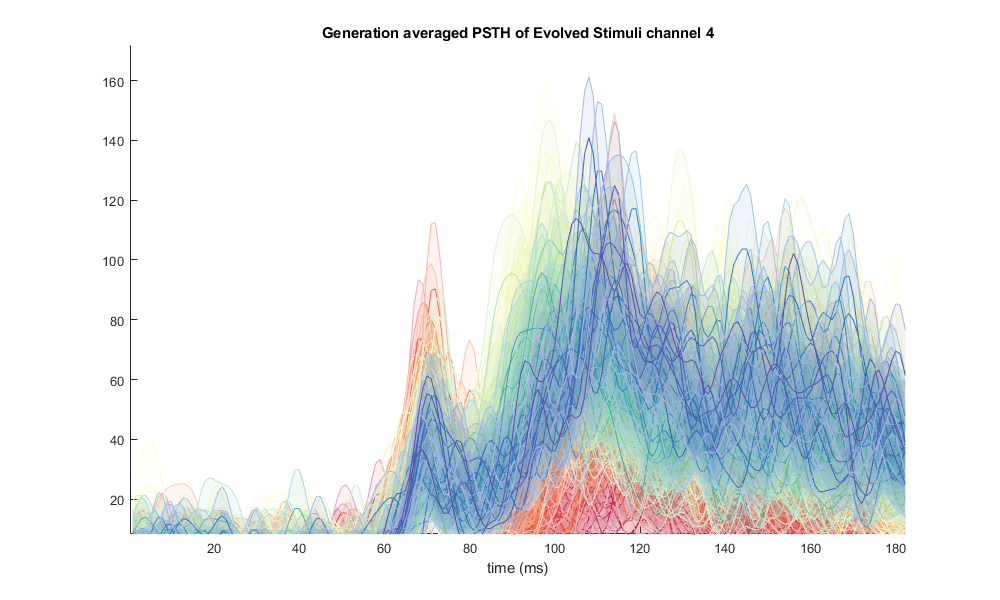

channel_j = 4; %1, 6, 30, 31 are bad silent channel 
figure('Position',[0,0,1000,600]);clf;hold on;
gen_list = 0:100;
for i = 1:length(gen_list)
    shadedErrorBar([],evol_stim_fr(i, :, channel_j),evol_stim_sem(i, :, channel_j),...
    'lineprops',{'Color',[color_seq(i, :),0.2]},'transparent',1,'patchSaturation',0.075)
    % plot(nat_stim_fr(i,:,channel_j))
end
YL=ylim;YL(1)=0;ylim(YL);
XL=xlim;XL(1)=0;xlim(XL);
xlabel("time (ms)")
title(['Generation averaged PSTH of Evolved Stimuli channel ', num2str(channel_j)])

mkdir 'Evolv_response'
cd 'Evolv_response'
for channel_j = 1:65 %1, 6, 30, 31 are bad silent channel 
figure('Position',[0,0,1000,600]);clf;hold on;
gen_list = 0:100;
for i = 1:length(gen_list)
    shadedErrorBar([],evol_stim_fr(i, :, channel_j),evol_stim_sem(i, :, channel_j),...
    'lineprops',{'Color',[color_seq(i, :),0.2]},'transparent',1,'patchSaturation',0.075)
    % plot(nat_stim_fr(i,:,channel_j))
end
YL=ylim;YL(1)=0;ylim(YL);
XL=xlim;XL(1)=0;xlim(XL);
xlabel("time (ms)")
title(['Generation averaged PSTH of Evolved Stimuli channel ', num2str(channel_j)])
saveas(gcf,sprintf("Evolv_rsp_channel%d.png",channel_j))
end
cd ..\

channel_j = 4; %1, 6, 30, 31 are bad silent channel 
figure('Position',[0,0,1000,600]);clf;hold on;
gen_list = 0:100;
for i = 1:length(gen_list)
    plot(evol_stim_fr(i, :, channel_j),'Color',[color_seq(i, :),0.2])
end
xlabel("time (ms)")
title(['Generation averaged PSTH of Evolved Stimuli channel ', num2str(channel_j)])

figure;
imagesc(evol_stim_fr(:, :, 45))

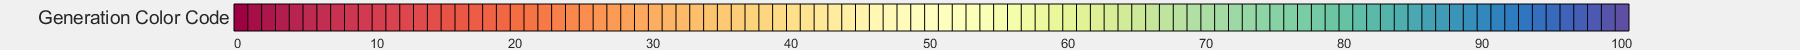

cbh = figure('Position', [500,400,1800,50]);
% for y = 1:ymx
%     num = raw(y).num;
%     typ = raw(y).typ;
%     map = raw(y).rgb(bmIndex(num,num,typ),:)/255; % downsample
y = 1; ymx=1.5; xmx = size(color_seq,1);
axh = axes('Parent',cbh, 'Color','none',...
	'XTick',0.5:10:xmx-0.5, 'YTick',0.5:ymx,'XTickLabel',{gen_list(1:10:end)},...
        'YTickLabel',{"Generation Color Code"},'YDir','reverse');
for x = 1:size(color_seq,1)
    patch([x-1,x-1,x,x],[y-1,y,y,y-1],1, 'FaceColor',color_seq(x,:), 'Parent',axh)
end
xlim([0, xmx])
axh.YAxis.FontSize = 14;
axh.XAxis.FontSize = 10;
set(gcf,'Visible','on')

% text(xmx+0.1,y-0.5,typ, 'Parent',axh, 'FontName',axf)
% end
saveas(gcf, ".\Evolv_response\Generation_Color_code.png")

### Clustering Analysis / Sorting of Transient Traces. 

channel_j = 4;
% cluster_input = rasters(sort_idx(gen_num_i~=-1), :, channel_j);
cluster_input = rasters(sort_idx(gen_num_i~=-1), :, channel_j);
Z = linkage(cluster_input, 'average', 'euclidean');%''correlation

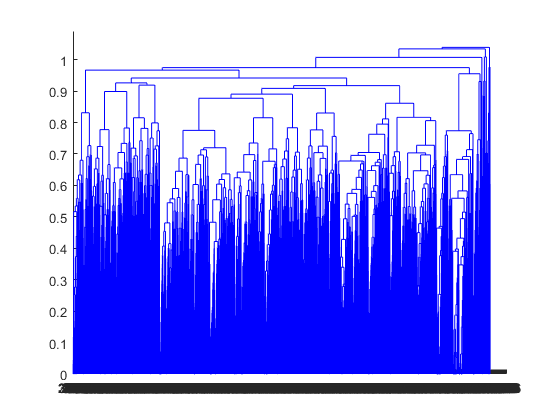

figure
[~, T , perm_indx] = dendrogram(Z,0);

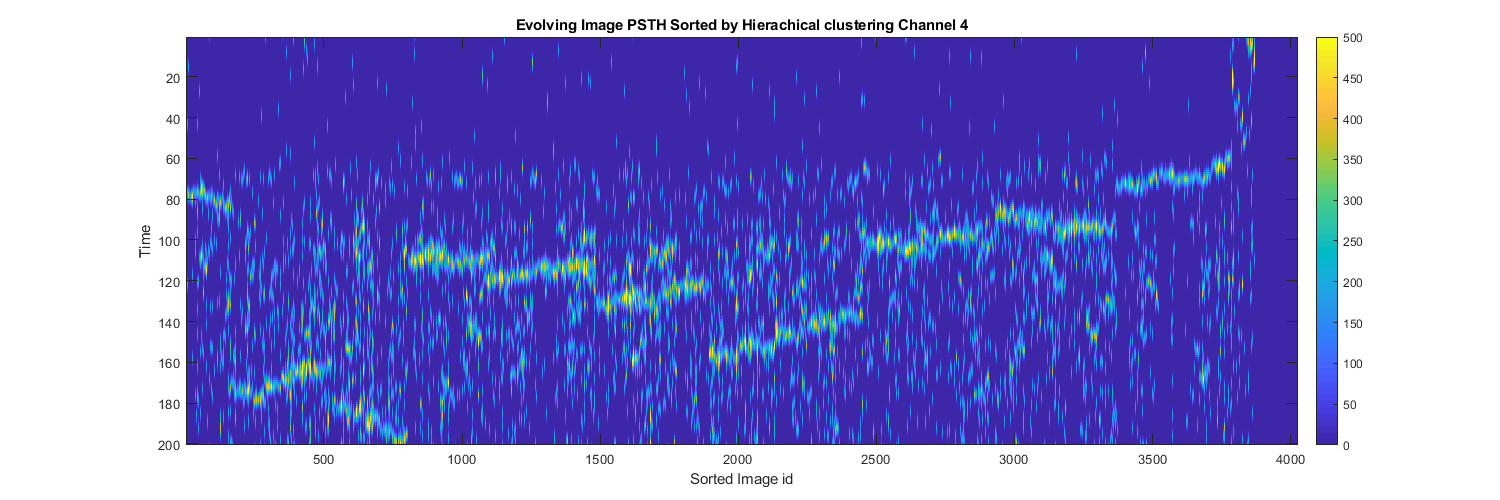

figure("Position",[0,0,1500,500])
imagesc(cluster_input(perm_indx, :)',[0,500])
colorbar()
title(sprintf("Evolving Image PSTH Sorted by Hierachical clustering Channel %d",channel_j))
ylabel("Time")
xlabel("Sorted Image id")

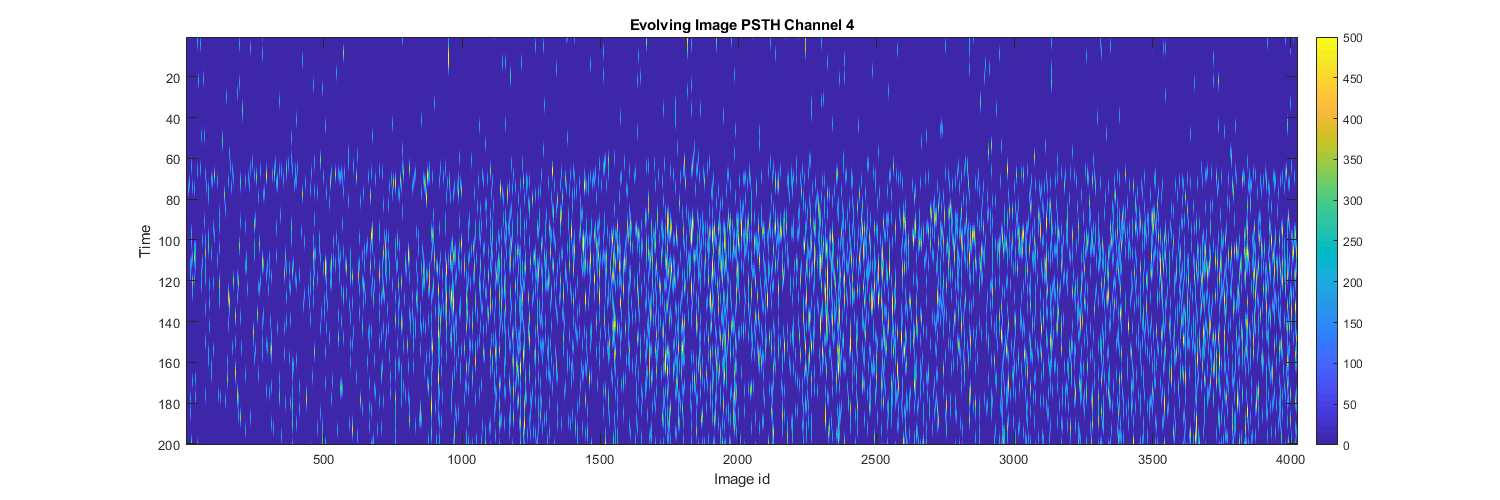

figure("Position",[0,0,1500,500])
imagesc(cluster_input(:, :)',[0,500])
colorbar()
title(sprintf("Evolving Image PSTH Channel %d",channel_j))
ylabel("Time")
xlabel("Image id")

channel_j = 28;
cluster_input = rasters(sort_idx(gen_num_i~=-1), :, channel_j);
Z = linkage(cluster_input, 'average', 'correlation');%''correlation
[~, T , perm_indx] = dendrogram(Z,0);
figure
imagesc(cluster_input(perm_indx, :)',[0,500])

trial_i=2;
eye_pos = Trials.eyeXY{trial_i};
figure(2);clf;hold on
plot(eye_pos(:,1), eye_pos(:,2))
Break_Fix = single(sum(eye_pos.^2, 2) > 1)
scatter(eye_pos(:,1), eye_pos(:,2), 5, 1+Break_Fix)
axis equal 
% xlim(Trials.XY{trial_i}(1) + [- 0.5, 0.5] * Trials.width{trial_i}(1))
% ylim(Trials.XY{trial_i}(2) + [- 0.5, 0.5] * Trials.width{trial_i}(1))